# Seyed Mohammad Amin Atyabi - 830402014

## Biomedical Signal Processing - Homework 5

# Fantasia Database

## **f1o01**

Directly plot ECG signal from .dat file

According to 250Hz sampling rate, the fist 2500 samples show the first 10 seconds of signal

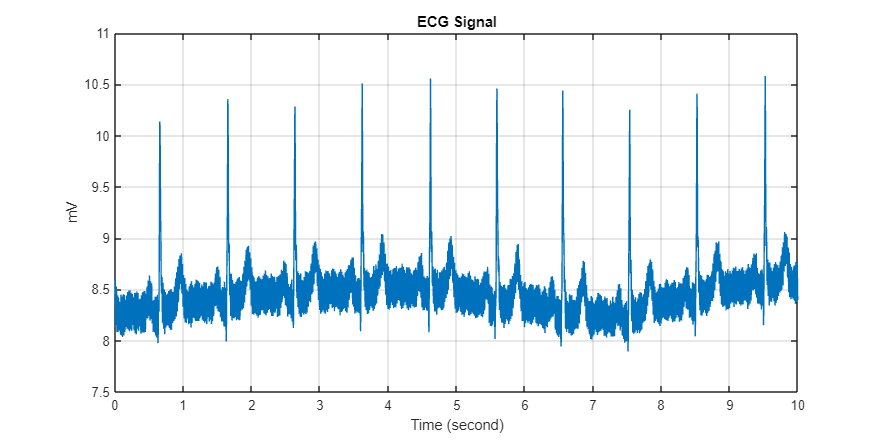

FS = 250;
[sig, ~, tm] = rdsamp('Data/f1o-01/f1o01.dat', 2, 10 * FS);
fig = figure(); 
fig.Position(3:4) = [3000, 1500];
plot(tm, sig);
title('ECG Signal');
xlabel('Time (second)');
ylabel('mV');
grid on;


$$y\left(n\right)=\frac{1}{T}\left\lbrack x\left(n\right)-x\left(n-1\right)\right\rbrack +0\ldotp 995y\left(n-1\right)$$


Given time domain filter is a **LTI **system. It can be rewrite in format below:


$$y\left(n\right)=\frac{1}{T}\;\left\lbrack 0\ldotp 995x\left(n\right)-0\ldotp 005x\left(n-1\right)\right\rbrack$$


This filter eliminates the low frequency noise witch in our case is the base line drift.

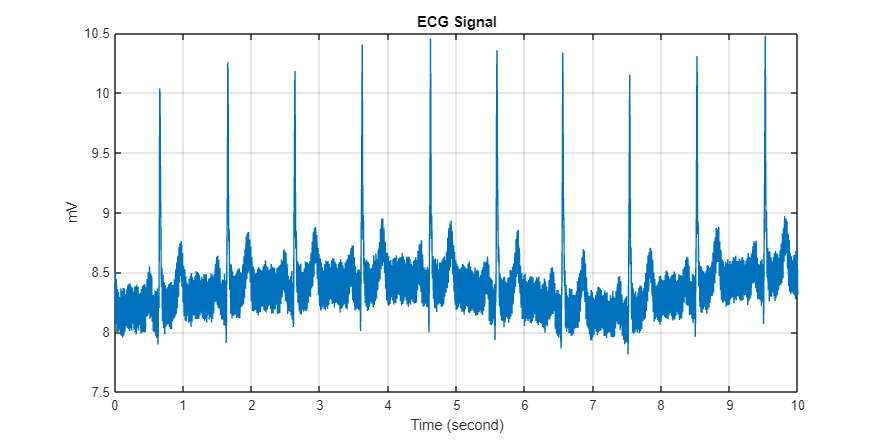

T = 1/FS;
filter_coeff = [0.995, -0.005];
sig_filterd = filter(filter_coeff, 1, sig, T);

fig = figure(); 
fig.Position(3:4) = [3000, 1500];
plot(tm, sig_filterd);
title('ECG Signal');
xlabel('Time (second)');
ylabel('mV');
grid on;

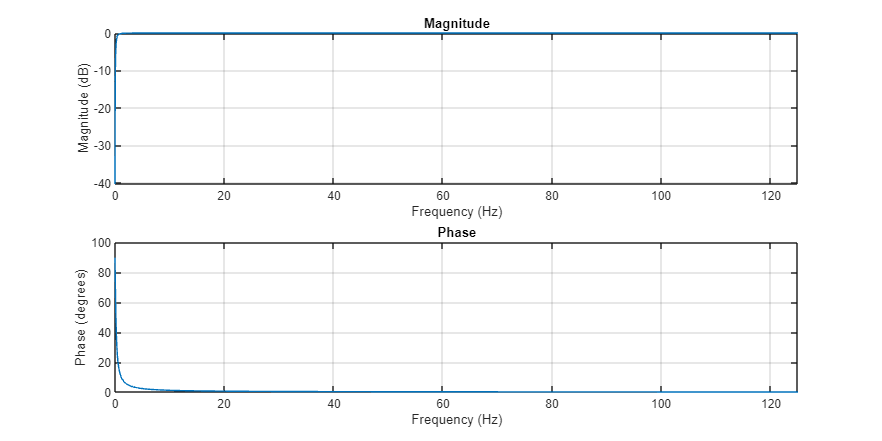

freqz([1 -1], [1 -0.995], 2^16, FS);

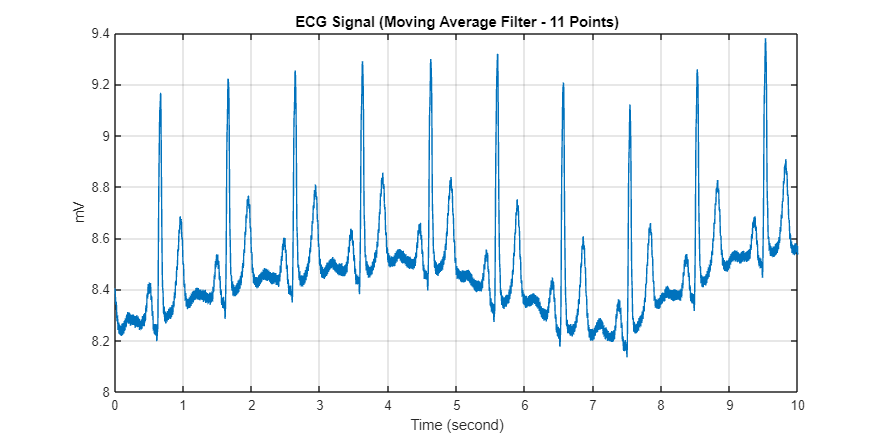

movingAverageFilter = movmean(sig, 11);
plot(tm, movingAverageFilter);
title('ECG Signal (Moving Average Filter - 11 Points)');
xlabel('Time (second)');
ylabel('mV');
grid on;

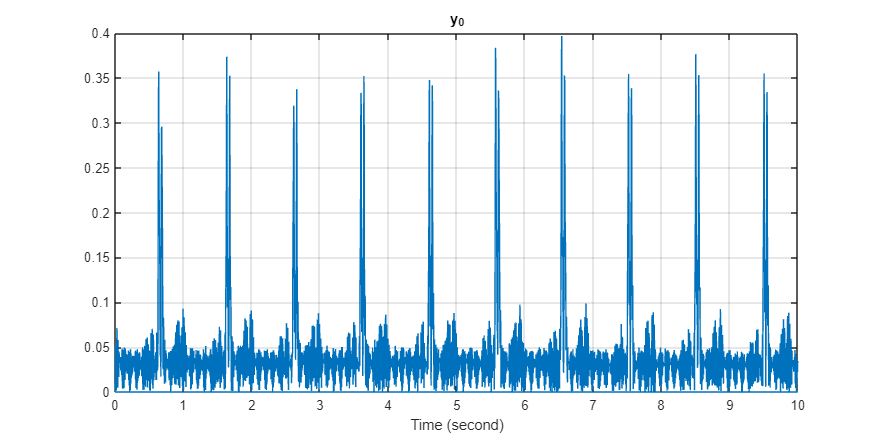

y0 = zeros(length(movingAverageFilter));
for n = 3:length(movingAverageFilter)
    y0(n) = abs(movingAverageFilter(n)-movingAverageFilter(n-2));
end
plot(tm, y0);
title('y_0');
xlabel('Time (second)');
grid on;

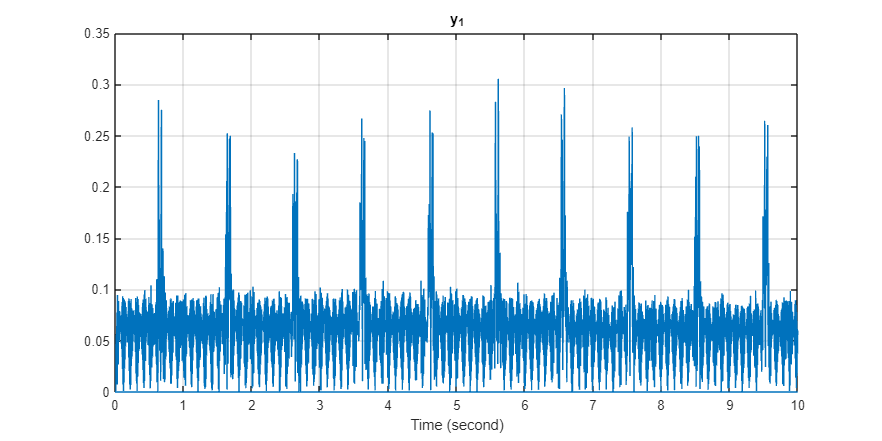

y1 = zeros(length(movingAverageFilter));
for n = 5:length(movingAverageFilter)
    y1(n) = abs(movingAverageFilter(n)-2*movingAverageFilter(n-2)+movingAverageFilter(n-4));
end
plot(tm, y1);
title('y_1');
xlabel('Time (second)');
grid on;

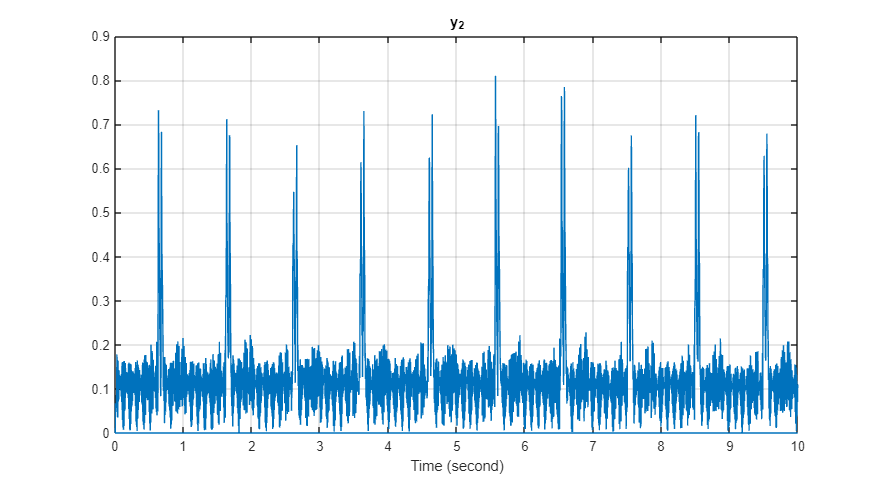

y2 = zeros(length(movingAverageFilter));
for n = 1:length(movingAverageFilter)
    y2(n) = 1.3*y0(n)+1.1*y1(n);
end
plot(tm, y2);
title('y_2');
xlabel('Time (second)');
grid on;

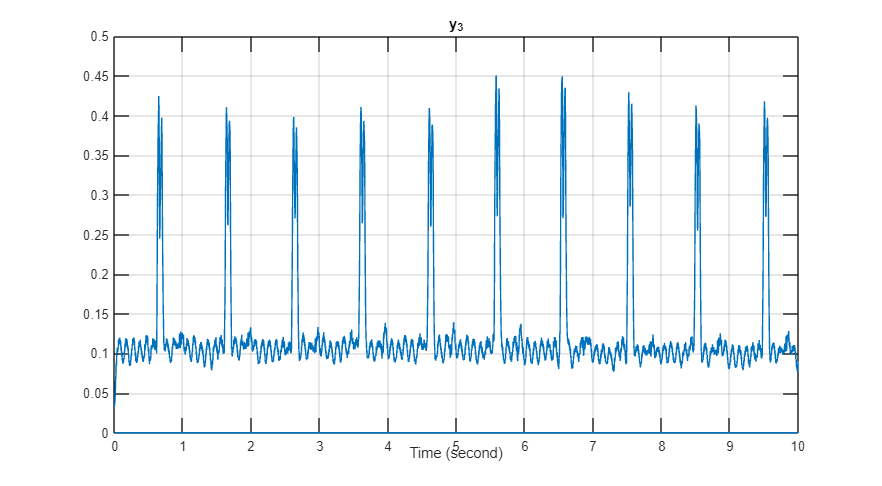

y3 = movmean(y2, 8);
plot(tm, y3);
title('y_3');
xlabel('Time (second)');
grid on;

# ECG-ID Database

## **person 1 - rec 14**

Directly plot ECG signal from .dat file

According to 500Hz sampling rate, the fist 5000 samples show the first 10 seconds of signal

FS = 500;
[sig, ~, tm] = rdsamp('Data/person 1 - rec 14/rec_14.dat', 1, 10 * FS);

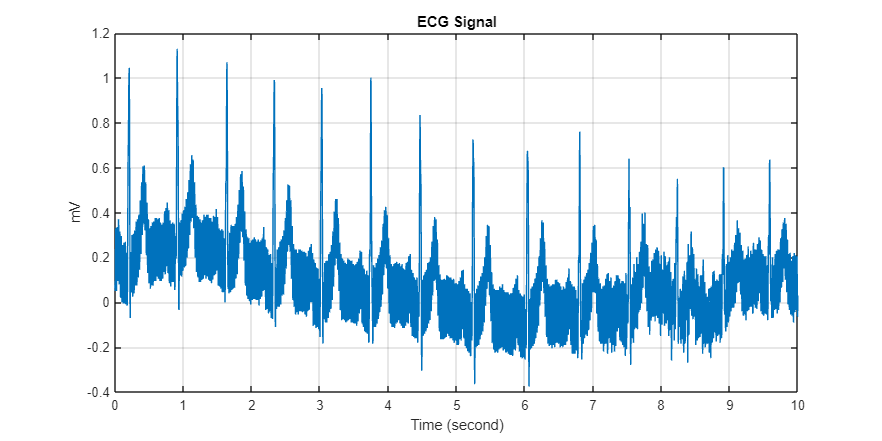

fig = figure(); 
fig.Position(3:4) = [3000, 1500];
plot(tm, sig);
title('ECG Signal');
xlabel('Time (second)');
ylabel('mV');
grid on;


$$y\left(n\right)=\frac{1}{T}\left\lbrack x\left(n\right)-x\left(n-1\right)\right\rbrack +0\ldotp 995y\left(n-1\right)$$


Given time domain filter is a **LTI **system. It can be rewrite in format below:


$$y\left(n\right)=\frac{1}{T}\;\left\lbrack 0\ldotp 995x\left(n\right)-0\ldotp 005x\left(n-1\right)\right\rbrack$$


This filter eliminates the low frequency noise witch in our case is the base line drift.

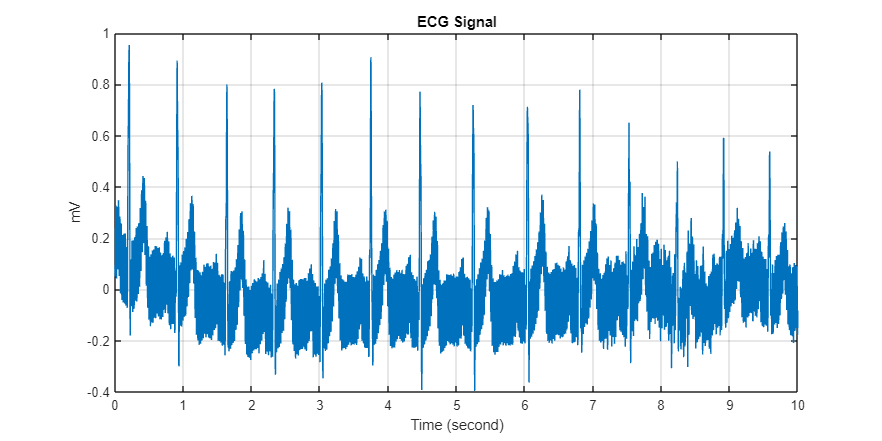

T = 1/FS;
filter_coeff = [0.995, -0.005];
sig_filterd = filter([1 -1], [1 -0.995], sig, T);

fig = figure(); 
fig.Position(3:4) = [3000, 1500];
plot(tm, sig_filterd);
title('ECG Signal');
xlabel('Time (second)');
ylabel('mV');
grid on;

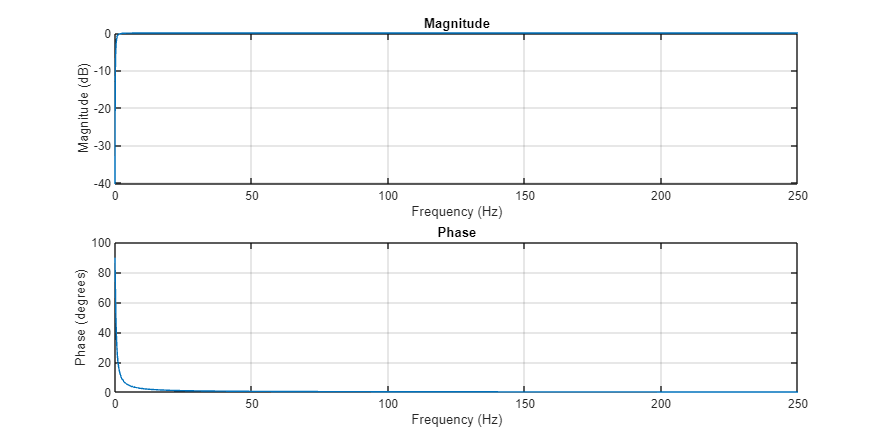

freqz([1 -1], [1 -0.995], 2^16, FS);

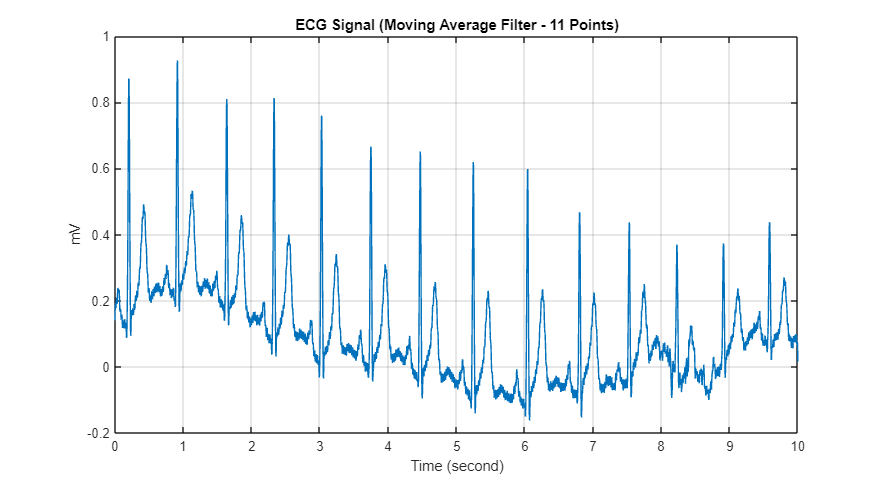

movingAverageFilter = movmean(sig, 11);
plot(tm, movingAverageFilter);
title('ECG Signal (Moving Average Filter - 11 Points)');
xlabel('Time (second)');
ylabel('mV');
grid on;

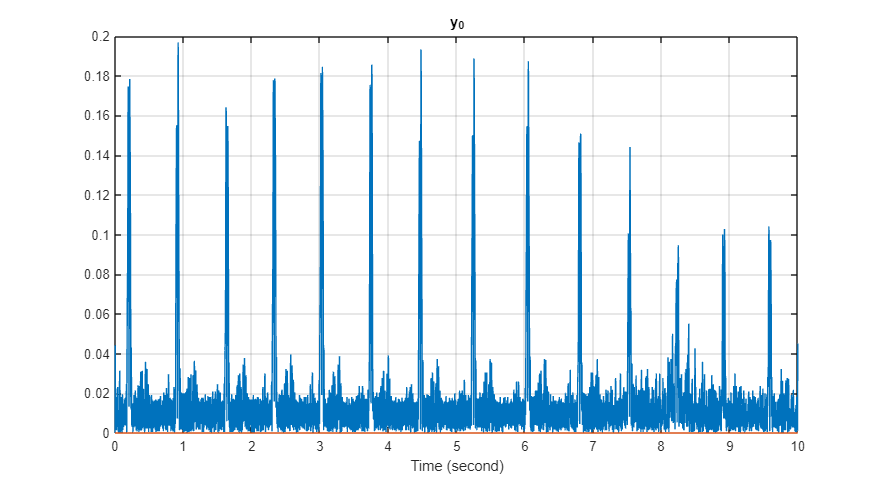

y0 = zeros(length(movingAverageFilter));
for n = 3:length(movingAverageFilter)
    y0(n) = abs(movingAverageFilter(n)-movingAverageFilter(n-2));
end
plot(tm, y0);
title('y_0');
xlabel('Time (second)');
grid on;

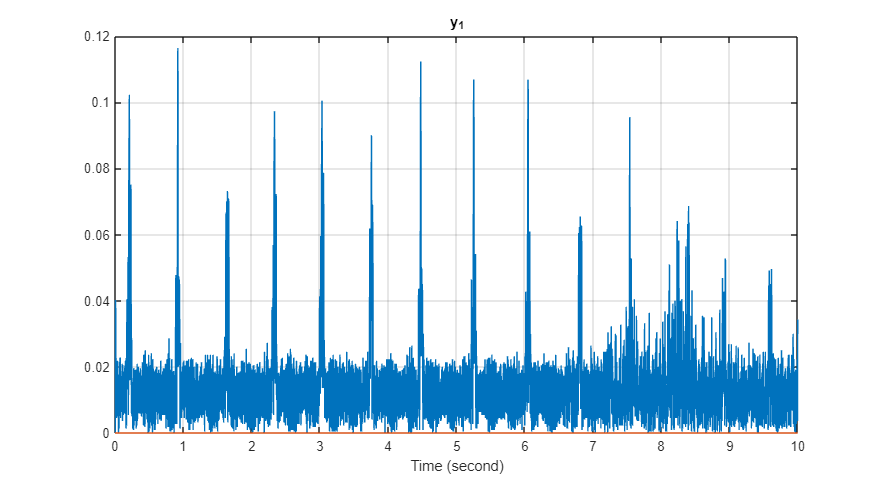

y1 = zeros(length(movingAverageFilter));
for n = 5:length(movingAverageFilter)
    y1(n) = abs(movingAverageFilter(n)-2*movingAverageFilter(n-2)+movingAverageFilter(n-4));
end
plot(tm, y1);
title('y_1');
xlabel('Time (second)');
grid on;

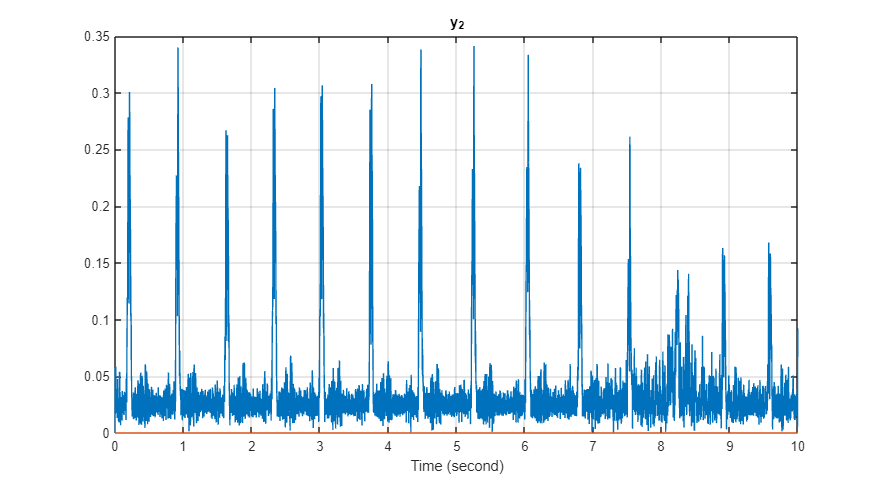

y2 = zeros(length(movingAverageFilter));
for n = 1:length(movingAverageFilter)
    y2(n) = 1.3*y0(n)+1.1*y1(n);
end
plot(tm, y2);
title('y_2');
xlabel('Time (second)');
grid on;

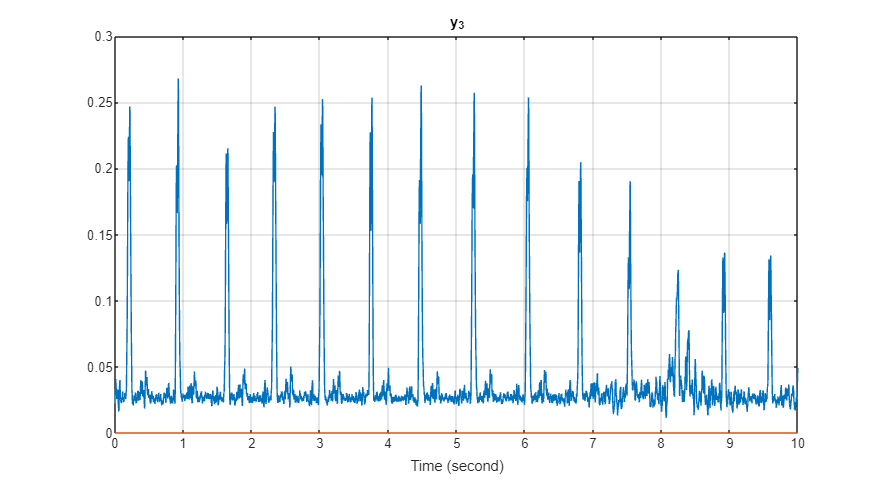

y3 = movmean(y2, 8);
plot(tm, y3);
title('y_3');
xlabel('Time (second)');
grid on;